## Evaluation script for a trained DQN agent

#### This script loads a previously trained RL agent and evaluates it in the environment. It shows the agent's performance in several test episodes.

clc;
clear all;
close all;


### Environment Configuration and Data Loading

**Note**: It is **CRITICAL** that the parameters and environment definition here are **EXACTLY** the same as those used during training.

fprintf('Loading parameters and defining the environment...\n');

Loading parameters and defining the environment...


%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('code');

Adding matlab path to: D:\code\SIM\code


% Load the same base parameters as in training
Parameters; % Script containing necessary variables 

total_iteration = 1

Wireless packet type: SC


N_y = 4

M_x = 15

M_y = 15

zeta =     0.9800    0.9810    0.9820    0.9830    0.9840    0.9850    0.9860    0.9870    0.9880    0.9890    0.9900    0.9910    0.9920    0.9930    0.9940    0.9950    0.9960    0.9970    0.9980    0.9990


T_coh = 0.0066

T = 4096

T = 144

SNR_dB = 11.6443


% Rebuild the EnvPars structure
EnvPars.N = evalin('base','N');
EnvPars.N_x = evalin('base','N_x');
EnvPars.N_y = evalin('base','N_y');
EnvPars.T = evalin('base','T');
EnvPars.T_x = evalin('base','T_x');
EnvPars.T_y = evalin('base','T_y');
EnvPars.SNR_dB = evalin('base','SNR_dB');

EnvPars.theta_min = evalin('base','theta_min');
EnvPars.theta_max = evalin('base','theta_max');
EnvPars.fc = evalin('base','fc');
EnvPars.lambda = evalin('base','lambda');
EnvPars.Ptx_dBm = evalin('base','Ptx_dBm');
EnvPars.Gtx_dBi = evalin('base','Gtx_dBi');
EnvPars.Grx_dBi = evalin('base','Grx_dBi');
EnvPars.txArray.NumElements = evalin('base','txArray.NumElements');
EnvPars.cdl = evalin('base','cdl');
EnvPars.var_noise_dB = evalin('base','var_noise_dB');
EnvPars.r = 0;

EnvPars.d_x = evalin('base','d_x');
EnvPars.pos_SIM = evalin('base','pos_SIM');
EnvPars.pos_MU  = [L_hall*rand(1,1)...
                   W_hall*rand(1,1)...
                   1.5];                 % Mobile user coordinates

EnvPars.maxSteps = EnvPars.T;
EnvPars.tolerance = tolerance;

% Environment variables
n = (1:EnvPars.N);
n_y = ceil(n ./ EnvPars.N_x);
n_x = n - (n_y - 1) .* EnvPars.N_x;
n_psi = n;
n_psi_y = ceil(n_psi ./ EnvPars.N_x);
n_psi_x = n_psi - (n_y - 1) .* EnvPars.N_x;
G_func = @(n,n_psi) exp(-1i*2*pi*(n_psi_x(n_psi)-1)/EnvPars.N_x.*(n_x(n)-1)).* ...
    exp(-1i*2*pi*(n_psi_y(n_psi)-1)/EnvPars.N_y.*(n_y(n)-1));
[n_psi_grid, n_s_grid] = ndgrid(1:EnvPars.N, 1:EnvPars.N);
EnvPars.G = G_func(n_s_grid, n_psi_grid);
t = (1:EnvPars.T);
EnvPars.t_y = ceil(t ./ EnvPars.T_x);
EnvPars.t_x = t - (EnvPars.t_y - 1) .* EnvPars.T_x;
EnvPars.U_func = @(n_, t_n_) exp(1i * ( ...
    -2*pi*(n_x(n_)-1) * (EnvPars.t_x(t_n_)-1) / (EnvPars.N_x*EnvPars.T_x) ...
    -2*pi*(n_y(n_)-1) * (EnvPars.t_y(t_n_)-1) / (EnvPars.N_y*EnvPars.T_y) ));

% Environment object
ObsInfo = rlNumericSpec([EnvPars.N 1]);
ActInfo = rlFiniteSetSpec(1:EnvPars.T);
StepHandle = @(Action, LoggedSignals) stepFunction(Action, LoggedSignals, EnvPars);
ResetHandle = @() resetFunction(EnvPars);
env = rlFunctionEnv(ObsInfo, ActInfo, StepHandle, ResetHandle);

% Load trained agent
try
    path_enhanced = fullfile('..', 'Dataset', 'dqn_phase_agent_enhanced.mat');
    load(path_enhanced, 'agent');
    fprintf('Trained agent successfully loaded.\n\n');
catch
    error('The agent file "dqn_phase_agent_mejorado.mat" could not be found. Make sure it is in the same folder.');
end

Trained agent successfully loaded.



### Evaluation for a given number of episodes

% Initial MU position
pos_MU = [2 0 1.5];   % (x0, y0, z0)

% Parameters
v = 1;         % speed in m/s along y-axis
t = 0:0.1:10;     % time vector in s
numEpisodesToTest = length(t);  % Number of test episodes you want to run
EnvPars.tolerance = pi/25;

% % Update position over time
% pos_MU_traj = [EnvPars.pos_MU(1) + v*t;              % x increases linearly   
%                repmat(EnvPars.pos_MU(2), size(t));   % y stays constant
%                repmat(EnvPars.pos_MU(3), size(t))];  % z stays constant

%% Random waypoint mobility model with random pause
% Required variables before running:
% L_hall   : hall length in x-direction
% W_hall   : hall width in y-direction
% v        : user speed [m/s]
% t        : time vector
% pos_MU   : initial position [x; y; z]
%
% Output:
% pos_MU_traj : 3 x length(t) trajectory matrix

% Example values (remove if already defined)
% L_hall = 20;
% W_hall = 10;
% v = 1.2;
% t = 0:0.1:100;
% pos_MU = [5; 3; 1.5];

%% Parameters for pause time
pause_min = 0.5;   % minimum pause duration [s]
pause_max = 3.0;   % maximum pause duration [s]

%% Initialization
Nt = length(t);
pos_MU_traj = zeros(3, Nt);

% Initial position
current_pos = pos_MU(:);
current_pos(1) = min(max(current_pos(1), 0), L_hall);
current_pos(2) = min(max(current_pos(2), 0), W_hall);

pos_MU_traj(:,1) = current_pos;

% Initial mobility state
state = "move";   % either "move" or "pause"

% First target waypoint
target_pos = [L_hall*rand; W_hall*rand; current_pos(3)];

% Pause handling
pause_end_time = -inf;

%% Time evolution
for k = 2:Nt
    
    dt = t(k) - t(k-1);
    
    % In case of non-positive time step, keep previous position
    if dt <= 0
        pos_MU_traj(:,k) = pos_MU_traj(:,k-1);
        continue;
    end
    
    if state == "move"
        
        % Vector toward target
        dvec = target_pos(1:2) - current_pos(1:2);
        dist_to_target = norm(dvec);
        travel_dist = v * dt;
        
        if dist_to_target <= travel_dist
            % Reach waypoint within this time step
            current_pos(1:2) = target_pos(1:2);
            
            % Switch to pause state
            pause_duration = pause_min + (pause_max - pause_min)*rand;
            pause_end_time = t(k) + pause_duration;
            state = "pause";
            
        else
            % Move toward waypoint
            direction = dvec / dist_to_target;
            current_pos(1:2) = current_pos(1:2) + direction * travel_dist;
        end
        
    elseif state == "pause"
        
        % Stay still during pause
        if t(k) >= pause_end_time
            % Pause finished, choose new waypoint and move again
            target_pos = [L_hall*rand; W_hall*rand; current_pos(3)];
            state = "move";
        end
        
    end
    
    % Store position
    pos_MU_traj(:,k) = current_pos;
end

% Enforce constant z-coordinate
pos_MU_traj(3,:) = pos_MU(3);


#### Ploting the mobility of the user

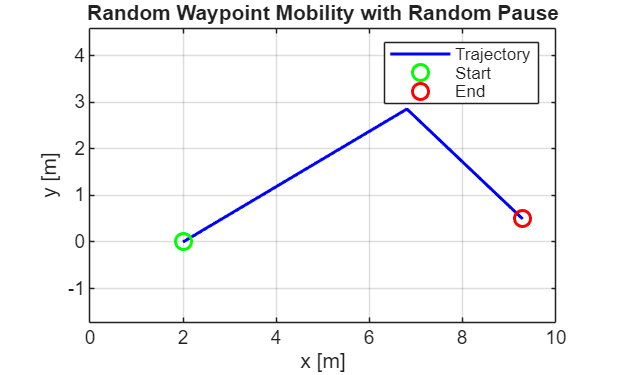

figure;
plot(pos_MU_traj(1,:), pos_MU_traj(2,:), 'b-', 'LineWidth', 1.5); hold on;
plot(pos_MU_traj(1,1), pos_MU_traj(2,1), 'go', 'MarkerSize', 8, 'LineWidth', 1.5);
plot(pos_MU_traj(1,end), pos_MU_traj(2,end), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
xlim([0 L_hall]);
ylim([0 W_hall]);
xlabel('x [m]');
ylabel('y [m]');
title('Random Waypoint Mobility with Random Pause');
grid on;
axis equal;
legend('Trajectory','Start','End');

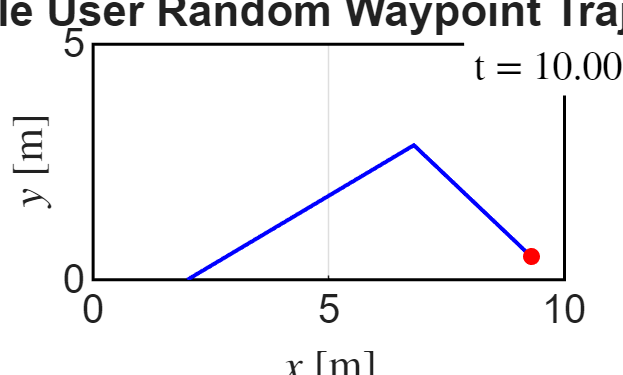


%% Animation of the mobile user trajectory

figure;
hold on;
grid on;
axis equal;
xlim([0 L_hall]);
ylim([0 W_hall]);
xlabel('$x$ [m]','Interpreter','latex');
ylabel('$y$ [m]','Interpreter','latex');
title('Mobile User Random Waypoint Trajectory');

% Draw hall boundary
rectangle('Position',[0, 0, L_hall, W_hall], 'EdgeColor','k', 'LineWidth',1.5);

% Plot full trajectory as dashed reference
plot(pos_MU_traj(1,:), pos_MU_traj(2,:), '--', 'Color', [0.7 0.7 0.7], 'LineWidth', 1);

% Initialize animated trajectory and current user marker
h_traj = plot(pos_MU_traj(1,1), pos_MU_traj(2,1), 'b-', 'LineWidth', 2);
h_user = plot(pos_MU_traj(1,1), pos_MU_traj(2,1), 'ro', ...
    'MarkerFaceColor','r', 'MarkerSize',8);

% Optional text showing current time
h_time = text(L_hall*(1-0.2), 0.91*W_hall, sprintf('$t = %.2f$ [s]', t(1)), ...
    'FontSize', font, 'Color', 'k','BackgroundColor','w','Interpreter','latex');

set(gca,'FontSize',font)

for k = 1:length(t)
    
    % Update traveled path
    set(h_traj, 'XData', pos_MU_traj(1,1:k), 'YData', pos_MU_traj(2,1:k));
    
    % Update current user position
    set(h_user, 'XData', pos_MU_traj(1,k), 'YData', pos_MU_traj(2,k));
    
    % Update time label
    set(h_time, 'String', sprintf('t = %.2f s', t(k)));
    
    drawnow;
    
    % Optional real-time pacing
    if k < length(t)
        pause(t(k+1) - t(k));
    end
end

% Preallocate/collect episode data
actions = [];
rewards = [];
psi_x_est_history = [];
psi_y_est_history = [];
psi_x_real = [];
psi_y_real = [];

for episode = 1:numEpisodesToTest
    % Update MU position
    EnvPars.pos_MU = pos_MU_traj(:,episode)';

    % Initialize episode using your resetFunction to obtain LoggedSignals
    [observation, LoggedSignals] = resetFunction(EnvPars);
    psi_x_real(episode) = LoggedSignals.psi_x_true;
    psi_y_real(episode) = LoggedSignals.psi_y_true;
    isDone = false;
    stepCount = 0;

    while ~isDone && stepCount < EnvPars.maxSteps
        % Choose action from agent policy (greedy, since epsilon=0)
        [action, ~] = getAction(agent, observation);

        % If action is a cell, extract its contents
        if iscell(action)
            action = action{1};
        end

        % Environment step using your stepFunction, keeping LoggedSignals
        [nextObs, reward, isDone, LoggedSignals] = stepFunction(action, LoggedSignals, EnvPars);

        % Log
        stepCount = stepCount + 1;
        actions(stepCount,episode) = double(action);
        rewards(stepCount,episode) = reward;
        psi_x_est_history(stepCount,episode) = LoggedSignals.psi_x_est;
        psi_y_est_history(stepCount,episode) = LoggedSignals.psi_y_est;
        % psi_x_est_history(stepCount,episode) = nextObs(1);
        % psi_y_est_history(stepCount,episode) = nextObs(2);

        % Advance
        observation = nextObs;
    end
    % psi_x_est(episode) = psi_x_est_history(find(psi_x_est_history(:,episode) ~= 0,1,'last'),episode);
    % psi_y_est(episode) = psi_y_est_history(find(psi_y_est_history(:,episode) ~= 0,1,'last'),episode);

    idx_x = find(psi_x_est_history(:,episode) ~= 0 & ~isnan(psi_x_est_history(:,episode)), 1, 'last');
    idx_y = find(psi_y_est_history(:,episode) ~= 0 & ~isnan(psi_y_est_history(:,episode)), 1, 'last');

    if ~isempty(idx_x)
        psi_x_est(episode) = psi_x_est_history(idx_x, episode);
    else
        psi_x_est(episode) = 0;   % or NaN, or previous value, depending on your logic
    end

    if ~isempty(idx_y)
        psi_y_est(episode) = psi_y_est_history(idx_y, episode);
    else
        psi_y_est(episode) = 0;   % or NaN, or previous value, depending on your logic
    end
end

### Figures

%% Animation of psi_x_real vs psi_x_est

figure;
hold on;
grid on;

xlabel('Time [s]','Interpreter','latex');
ylabel('$\psi_x$','Interpreter','latex');
title('$\psi_x$ Real vs Estimated','Interpreter','latex');

% Axis limits (auto-adapt nicely)
xmin = min(t);
xmax = max(t);

ymin = min([psi_x_real(:); psi_x_est(:)]);
ymax = max([psi_x_real(:); psi_x_est(:)]);

% Add small margins
margin = 0.1*(ymax - ymin + eps);
ylim([ymin - margin, ymax + margin]);
xlim([xmin xmax]);

% Initialize lines
h_real = plot(t(1), psi_x_real(1), 'b-', 'LineWidth', 2);
h_est  = plot(t(1), psi_x_est(1), 'r--', 'LineWidth', 2);



% Moving markers (like two actors on stage 🎭)
h_real_pt = plot(t(1), psi_x_real(1), 'bo', 'MarkerFaceColor','b');
h_est_pt  = plot(t(1), psi_x_est(1), 'ro', 'MarkerFaceColor','r');

legend([h_real,h_est],{'Real','Estimated'});

set(gca, 'YTick', [0,pi/2,pi,3*pi/2,2*pi]);
y_ticks=cell(1,5);
x_ticks{1}="$0$";
x_ticks{2}="$\pi/2$";
x_ticks{3}="$\pi$";
x_ticks{4}="$3\pi/2$";
x_ticks{5}="$2\pi$";
set(gca, 'YTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');

% Time label
h_time = text(xmin + 0.02*(xmax-xmin), ymax, ...
    sprintf('$t = %.2f$ s', t(1)), ...
    'FontSize', font, ...
    'BackgroundColor', 'w','Interpreter','latex');

set(gca,'FontSize',font);

%% Animation loop
for k = 1:length(t)
    
    % Update full curves up to time k
    set(h_real, 'XData', t(1:k), 'YData', psi_x_real(1:k));
    set(h_est,  'XData', t(1:k), 'YData', psi_x_est(1:k));
    
    % Update moving markers
    set(h_real_pt, 'XData', t(k), 'YData', psi_x_real(k));
    set(h_est_pt,  'XData', t(k), 'YData', psi_x_est(k));
    
    % Update time text
    set(h_time, 'String', sprintf('t = %.2f s', t(k)));
    
    drawnow;
    
    % Optional real-time pacing
    if k < length(t)
        pause(t(k+1) - t(k));
    end
end


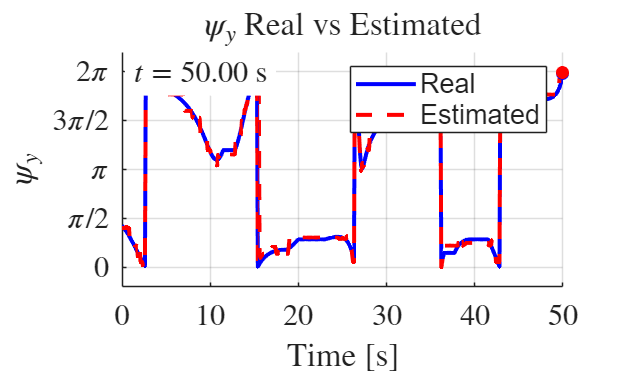

%% Animation of psi_y_real vs psi_y_est

figure;
hold on;
grid on;

xlabel('Time [s]','Interpreter','latex');
ylabel('$\psi_y$','Interpreter','latex');
title('$\psi_y$ Real vs Estimated','Interpreter','latex');

% Axis limits (auto-adapt nicely)
xmin = min(t);
xmax = max(t);

ymin = min([psi_y_real(:); psi_y_est(:)]);
ymax = max([psi_y_real(:); psi_y_est(:)]);

% Add small margins
margin = 0.1*(ymax - ymin + eps);
ylim([ymin - margin, ymax + margin]);
xlim([xmin xmax]);

% Initialize lines
h_real = plot(t(1), psi_y_real(1), 'b-', 'LineWidth', 2);
h_est  = plot(t(1), psi_y_est(1), 'r--', 'LineWidth', 2);

% Moving markers
h_real_pt = plot(t(1), psi_y_real(1), 'bo', 'MarkerFaceColor','b');
h_est_pt  = plot(t(1), psi_y_est(1), 'ro', 'MarkerFaceColor','r');

legend([h_real,h_est],{'Real','Estimated'});

% Y ticks in radians
set(gca, 'YTick', [0,pi/2,pi,3*pi/2,2*pi]);
y_ticks = cell(1,5);
y_ticks{1} = "$0$";
y_ticks{2} = "$\pi/2$";
y_ticks{3} = "$\pi$";
y_ticks{4} = "$3\pi/2$";
y_ticks{5} = "$2\pi$";
set(gca, 'YTickLabel', y_ticks, 'TickLabelInterpreter', 'latex');

% Time label
h_time = text(xmin + 0.02*(xmax-xmin), ymax, ...
    sprintf('$t = %.2f$ s', t(1)), ...
    'FontSize', font, ...
    'BackgroundColor', 'w', ...
    'Interpreter','latex');

set(gca,'FontSize',font);

%% Animation loop
for k = 1:length(t)
    
    % Update full curves
    set(h_real, 'XData', t(1:k), 'YData', psi_y_real(1:k));
    set(h_est,  'XData', t(1:k), 'YData', psi_y_est(1:k));
    
    % Update markers
    set(h_real_pt, 'XData', t(k), 'YData', psi_y_real(k));
    set(h_est_pt,  'XData', t(k), 'YData', psi_y_est(k));
    
    % Update time text
    set(h_time, 'String', sprintf('$t = %.2f$ s', t(k)));
    
    drawnow;
    
    if k < length(t)
        pause(t(k+1) - t(k));
    end
end



% % Animation
% figure;
% for k = 1:numEpisodesToTest
%     % --- Subplot 1: MU trajectory ---
%     subplot(3,1,1);
%     plot(pos_MU_traj(1,1:k), pos_MU_traj(2,1:k), 'b-', 'LineWidth', 2); hold on;
%     plot(Pos_SIM(1), Pos_SIM(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
%     plot(pos_MU_traj(1,k), pos_MU_traj(2,k), 'ks', 'MarkerSize', 8, 'LineWidth', 2);
%     xlabel('x [m]'); ylabel('y [m]');
%     title('MU Trajectory'); grid on; axis([0 L_hall 0 W_hall]);
% 
%     % --- Subplot 2: psi_x tracking ---
%     subplot(3,1,2);
%     plot(t(1:k), psi_x_real(1:k), 'b-o', 'LineWidth', 2); hold on;
%     plot(t(1:k), psi_x_est(1:k), 'r--o', 'LineWidth', 2);
%     xlabel('Time [s]'); ylabel('\psi_x [rad]');
%     legend('Real','Estimated'); title('Tracking \psi_x'); grid on;
% 
%     % --- Subplot 3: psi_y tracking ---
%     subplot(3,1,3);
%     plot(t(1:k), psi_y_real(1:k), 'b-o', 'LineWidth', 2); hold on;
%     plot(t(1:k), psi_y_est(1:k), 'r--o', 'LineWidth', 2);
%     xlabel('Time [s]'); ylabel('\psi_y [rad]');
%     legend('Real','Estimated'); title('Tracking \psi_y'); grid on;
% 
%     drawnow;
% end
% 
% % Metrics
% % Absolute error per step
% err_x = psi_x_est - psi_x_real;
% err_y = psi_y_est - psi_y_real;
% 
% % Plot comparison
% figure;
% plot(err_x, err_y, 'o', 'LineWidth', 1.5);
% xlim([0 pi/9])
% ylim([0 pi/9])
% xlabel('Error in \psi_x');
% ylabel('Error in \psi_y');
% title('Per-step comparison: \psi_x vs \psi_y');
% grid on;
% 
% % RMSE
% rmse_psi_x = rmse(psi_x_est,psi_x_real)
% rmse_psi_y = rmse(psi_y_est,psi_y_real)
% % Todo: CDF of RMSE with multiple iterations
% 
% % Angle accuracy
% angleAcc = sqrt((err_x).^2 + (err_y).^2);
% 
% figure;
% plot(angleAcc, 'bo-', 'LineWidth', 1.5);
% xlabel('step');
% ylabel('Angle accuracy');
% title('Angle Accuracy per Sample');
% grid on;
% 
% % figure;
% % histogram(pointAcc, 10);
% % xlabel('Error magnitude');
% % ylabel('Frequency');
% % title('Distribution of Point Accuracy');
% % grid on;
% 
% % Final score
% M_min = pi/9; % biggest acceptable error
% M_max = mean(angleAcc); % desired average localization error
% score_x = evarilos_score(angleAcc,M_min,M_max,1)
% 
% figure;
% plot(score_x, 'b-', 'LineWidth', 1.5);
% ylabel('Score')
% xlabel('Steps')
% title('Final score')
% grid on


#### Functions

% Functions
function score = evarilos_score(m, M_min, M_max, weight)
    % EVARILOS Benchmarking Handbook scoring function
    % m      : measured metric value (scalar or vector)
    % M_min  : minimal acceptable value (biggest acceptable error)
    % M_max  : maximal acceptable value (desired average localization error)
    % weight : weighting factor (default = 1 if not provided)

    if nargin < 4
        weight = 1; % default weight
    end

    % Linear translation function
    raw_score = 10 * (m - M_min) ./ (M_max - M_min);

    % Clip between 0 and 10
    clipped_score = max(0, min(10, raw_score));

    % Apply weighting factor
    score = weight * clipped_score;
end

function addingPathParentFolderByName(targetName)
    %Place the matlab directory at the right position
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

#### Alternative evaluation

% %% Simulation Configuration
% % For the evaluation, we disable random exploration.
% % The agent will only use the policy it has learned (exploitation).
% agent.AgentOptions.EpsilonGreedyExploration.EpsilonMin = 0;
% agent.AgentOptions.EpsilonGreedyExploration.Epsilon = 0;
% 
% numEpisodesToTest = 5; % Number of test episodes you want to run
% simOptions = rlSimulationOptions('MaxSteps', EnvPars.maxSteps);
% 
% fprintf('Starting evaluation for %d episodes...\n', numEpisodesToTest);
% fprintf('----------------------------------------\n');
% 
% %% Simulation and Visualization Loop
% for episode = 1:numEpisodesToTest
% 
%     % Reset the environment for a new episode
%     % The reset function will generate new random angles psi_x and psi_y
%     observation = reset(env);
% 
%     % Simulate the episode
%     experience = sim(agent, env, simOptions);
% 
%     % Extract episode data for analysis
%     % The experience is stored in the format (Observation, Action, Reward, NextObservation, IsDone)
%     actions = experience.Action.actions.Data;
%     rewards = experience.Reward.Data;
%     observations = experience.Observation.observations.Data;
% 
%     % The final state contains information from the last step, including the true angles
%     finalInfo = experience.LoggedSignals{end};
%     psi_x_true = finalInfo.psi_x_true;
%     psi_y_true = finalInfo.psi_y_true;
% 
%     % Extract the trajectory of the angle estimates
%     psi_x_est_history = squeeze(observations(1,1,:));
%     psi_y_est_history = squeeze(observations(2,1,:));
% 
%     % Display episode statistics
%     stepsTaken = numel(actions);
%     totalReward = sum(rewards);
%     finalError = finalInfo.error_sum;
% 
%     fprintf('Episode %d:\n', episode);
%     fprintf('  - True Angle (psi_x, psi_y): (%.3f, %.3f)\n', psi_x_true, psi_y_true);
%     fprintf('  - Final Estimated Angle:     (%.3f, %.3f)\n', psi_x_est_history(end), psi_y_est_history(end));
%     fprintf('  - Steps taken: %d / %d\n', stepsTaken, EnvPars.maxSteps);
%     fprintf('  - Total final error: %.4f\n', finalError);
%     fprintf('  - Accumulated reward: %.2f\n', totalReward);
%     fprintf('----------------------------------------\n');
% 
%     % Visualize episode results
%     figure('Name', ['Evaluation Episode Results ' num2str(episode)]);
% 
%     % Subplot 1: psi_x estimation trajectory
%     subplot(2, 1, 1);
%     plot(1:stepsTaken, psi_x_est_history, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4);
%     hold on;
%     yline(psi_x_true, 'r--', 'LineWidth', 2);
%     title(['\psi_x Estimation vs. Steps (Episode ' num2str(episode) ')']);
%     xlabel('Step');
%     ylabel('\psi_x Value');
%     legend('Estimated', 'True');
%     grid on;
% 
%     % Subplot 2: psi_y estimation trajectory
%     subplot(2, 1, 2);
%     plot(1:stepsTaken, psi_y_est_history, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4);
%     hold on;
%     yline(psi_y_true, 'r--', 'LineWidth', 2);
%     title(['\psi_y Estimation vs. Steps (Episode ' num2str(episode) ')']);
%     xlabel('Step');
%     ylabel('\psi_y Value');
%     legend('Estimated', 'True');
%     grid on;
% 
%     % Optional: Plot the actions taken
%     figure('Name', ['Actions Taken - Episode ' num2str(episode)]);
%     stem(1:stepsTaken, squeeze(actions), 'filled');
%     title('Sequence of Taken Actions (t_{\psi})');
%     xlabel('Step');
%     ylabel('Action Index');
%     grid on;
% end
